# **Brightside Braking System Calculations**

This MATLAB Live Script was used as an aid in the design of the braking system for Brightside. It is largely focused on back-calculating forces through the complete braking system including the wheels, brake calipers, brake lines, proportioning valves, and pedals.

The script is divided into three major areas:

- definition of the car and target parameters,

- calculation of wheel normal forces, line pressures, and pedal forces

- estimation of the stopping distance of the car using the above calculated values.

To use this script, please follow these steps:

- Input car parameters from Solidworks, ANSYS, Lotus, hand calculations, etc. in the "**Car Parameters**" section. **Ensure that the units listed in the comment beside each parameter is followed!**

- Input target design parameters in the "**Design Targets**" section of the script. These inputs are used as a point of comparison for the outputs of the program. It is important that "**targetBrakingEfficiency**" is set correctly.

- Run this section **before** the "**Car Stopping Distance Estimate**" calculation. The stopping distance calculation uses the parameters set during the tuning of the system to 

**Sam Bonnell, Vehicle Dynamics Lead, 2022-2024**

**Date written: 2023-11-01**

clear; clc; clf;
format long g

#### Constants

% Physical Constants
G = 9.81;

% Conversion Factors
PAtoPSI = 6895;
LbftoN = 4.448;
IN2toM2 = 1550;
INtoM = 39.37;

% Extracts balljoint coordinates from google sheets
ID = '1UxrHRz9iydKkYqhXAQWLDXY1FJoSzHCgv_TjBJgwtKQ';
sheet_name = 'Hardpoints';
url_name = sprintf('https://docs.google.com/spreadsheets/d/%s/gviz/tq?tqx=out:csv&sheet=%s',...
    ID, sheet_name);
data = webread(url_name);

#### **Car Parameters**

MASS = sum(data.X(1:2));                                        % (kg) Total mass sum of driver and Brightside
COM = [data.X(3), data.Y(3), data.Z(3)]./1000;                  % (m) Pull the centre of mass from the spreadsheet of hardpoints
FRONT_TP = data.X(20);                                          % (m) Distance from origin to the front tire contact patch
REAR_TP = data.X(35);                                           % (m) Distance from origin to the rear tire contact patch

LEN_FRONT = abs(FRONT_TP - COM(1));                             % (m) Distance from centre of mass to front wheel contact patch
LEN_REAR = abs(REAR_TP - COM(1));                               % (m) Distance from centre of mass to rear wheel contact patch
COM_HEIGHT = COM(3);                                            % (m) Distance from centre of mass to plane defined by contact patch of front and rear wheels

epsilon = linspace(0,1.2,100)';

WHEEL_RAD = 0.283;                                              % (m) Radius from centre of rotation to contact patch
WHEEL_COF = 0.70;                                               % (N/A) Coefficient of grip between ground and tires
DISC_COF = 0.4;                                                 % (N/A) Coefficient of grip between brake pads and discs

DISC_RAD = [0.110 0.110 0.110 0.1428]';                         % (m) Front Left, Front Right, Back Left, Back Right
DISC_DIA = [0.220 0.220 0.220 2*0.1428]';                       % (m) Front Left, Front Right, Back Left, Back Right
CALIPER_DIA = [1/INtoM 1/INtoM 1/INtoM 1/INtoM 0.625/INtoM]';   % (m) Front Left, Front Right, Back Left, Back Right, Master Cylinder

PROPVALVE_FRONT_RED =53/100;              % (percentage/100) Proportioning valve maximum reduction
PROPVALVE_REAR_RED = 23/100;

% First row is the input points relative to the pivot of the pedal and the input force angle
% Second row is the master cylinder mounting point relative to the pivot of the pedal and the angle the master cylinder makes with the baseplate at rest
% Point are stored as x, y, theta

PEDAL_OUTPUT =  [30 181.045 0];
PEDAL_INPUT =   [12.68125 45.045 17.02];

PEDAL = [
    PEDAL_OUTPUT;
    PEDAL_INPUT
];

BALANCEBAR_BIAS = 62/100;               % Percentage of the input force that is passed to the front master cylinder versus the rear master cylinder

#### Design Targets

TARGET_EFFICIENCY = 0.5;
TARGET_INPUT = 890;
TARGET_ERROR = 10;

## Normal Forces During Braking

% Normal forces experienced by the front wheels during braking at the
% target efficiency with the specified coefficient of friction
FORCE_NORMAL_FRONT = (MASS*G)*(LEN_REAR + TARGET_EFFICIENCY*COM_HEIGHT)/(LEN_FRONT + LEN_REAR);

% Normal forces experienced by the rear wheels during braking at the
% target efficiency with the specified coefficient of friction
FORCE_NORMAL_REAR = (MASS*G)*(LEN_FRONT - TARGET_EFFICIENCY*COM_HEIGHT)/(LEN_FRONT + LEN_REAR);

round(100*FORCE_NORMAL_REAR/(FORCE_NORMAL_FRONT + FORCE_NORMAL_REAR),2)

ans =                      28.34


round(100*FORCE_NORMAL_FRONT/(FORCE_NORMAL_FRONT + FORCE_NORMAL_REAR),2)

ans =                      71.66


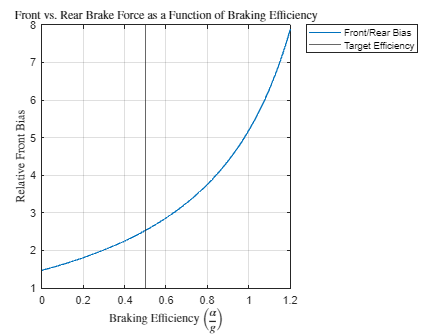

% Ratio of front to rear normal forces as a function of braking efficiency
R = (LEN_REAR+epsilon*COM_HEIGHT)./(LEN_FRONT-epsilon*COM_HEIGHT);

% Plot the relative bias as a function of braking efficiency
plot(epsilon, R);
hold on;
xline(TARGET_EFFICIENCY);
hold off;
title("Front vs. Rear Brake Force as a Function of Braking Efficiency", "Interpreter","latex")
xlabel("Braking Efficiency $\left(\frac{\alpha}{g}\right)$", "Interpreter","latex")
ylabel("Relative Front Bias", "Interpreter","latex")
legend("Front/Rear Bias", "Target Efficiency", "Location","northeastoutside")
grid on;

**CHECK - **If this value is negative, the car does not possess enough grip to stop. If positive, the car has enough grip

BRK_CHECK = round(MASS*G*WHEEL_COF - (WHEEL_COF)*(FORCE_NORMAL_FRONT + FORCE_NORMAL_REAR),3);

## **Brake Line Pressures**

PRESSURE = [0 0 0 0]'; % Front Left, Front Right, Back Left, Back Right
PRESSURE(1) = (4/(DISC_COF*pi*CALIPER_DIA(1)^2))*(WHEEL_RAD/(DISC_DIA(1)/2))*(WHEEL_COF*(FORCE_NORMAL_FRONT/2)); % Front Left
PRESSURE(2) = (4/(DISC_COF*pi*CALIPER_DIA(2)^2))*(WHEEL_RAD/(DISC_DIA(2)/2))*(WHEEL_COF*(FORCE_NORMAL_FRONT/2)); % Front Right
PRESSURE(3) = (4/(DISC_COF*pi*CALIPER_DIA(3)^2))*(WHEEL_RAD/(DISC_DIA(3)/2))*(WHEEL_COF*(FORCE_NORMAL_REAR/2)); % Back Left
PRESSURE(4) = (4/(DISC_COF*pi*CALIPER_DIA(4)^2))*(WHEEL_RAD/(DISC_DIA(4)/2))*(WHEEL_COF*(FORCE_NORMAL_REAR/2)); % Back Right

#### Brake Line Bias

PROPVALVE_FRONT_TARGET = (1 - PRESSURE(3)/PRESSURE(1))*100;
PROPVALVE_REAR_TARGET = (1 - PRESSURE(4)/PRESSURE(3))*100;

#### Proportioning Valve Conformation

PROPVALVE_ERROR = (PRESSURE(3) - PRESSURE(1)*(1-PROPVALVE_FRONT_RED))/PAtoPSI;

#### **Brake Pedal Output Pressure at Target Input**

A = PEDAL(1,1)*sind(PEDAL(1,3)) - PEDAL(1,2)*cosd(PEDAL(1,3));
B = PEDAL(2,1)*sind(PEDAL(2,3)) - PEDAL(2,2)*cosd(PEDAL(2,3));

#### Calculate Difference Required Pedal Input Force to Lock Brakes

set = [0 0 0]';

PEDAL_FORCES.FRONT_OUT = 0;
PEDAL_FORCES.FRONT_IN = 0;
PEDAL_FORCES.REAR_L_IN = 0;
PEDAL_FORCES.REAR_R_IN = 0;

for PEDAL_FORCE_INPUT = 50*LbftoN:1*LbftoN:750*LbftoN
    PEDAL_FORCE_OUTPUT = (A/B)*PEDAL_FORCE_INPUT;
    if (force2pressure(PEDAL_FORCE_OUTPUT*BALANCEBAR_BIAS, CALIPER_DIA(5), "m", "imperial") - (PRESSURE(1)/PAtoPSI) > 0 && set(1) ~= 1)
        PEDAL_FORCES.FRONT_OUT = PEDAL_FORCE_OUTPUT;
        PEDAL_FORCES.FRONT_IN = PEDAL_FORCE_INPUT;
        set(1) = 1;
    end

    if ((1-PROPVALVE_FRONT_RED)*force2pressure(PEDAL_FORCE_OUTPUT*(1-BALANCEBAR_BIAS), CALIPER_DIA(5), "m", "imperial") - (PRESSURE(3)/PAtoPSI) > 0 && set(2) ~= 1)
        PEDAL_FORCES.REAR_L_IN = PEDAL_FORCE_INPUT;
        set(2) = 1;
    end

    if ((1-PROPVALVE_REAR_RED)*(1-PROPVALVE_FRONT_RED)*force2pressure(PEDAL_FORCE_OUTPUT*(1-BALANCEBAR_BIAS), CALIPER_DIA(5), "m", "imperial") - (PRESSURE(4)/PAtoPSI) > 0 && set(3) ~= 1)
        PEDAL_FORCES.REAR_R_IN = PEDAL_FORCE_INPUT;
        set(3) = 1;
    end
end

baseForceY = PEDAL_FORCES.FRONT_IN*sind(PEDAL(1,3)) - PEDAL_FORCES.FRONT_OUT*sind(PEDAL(2,3));
baseForceX = PEDAL_FORCES.FRONT_IN*cosd(PEDAL(1,3)) - PEDAL_FORCES.FRONT_OUT*cosd(PEDAL(2,3));

lockUpForceError = PEDAL_FORCES.REAR_L_IN - TARGET_INPUT;

PEDAL_FORCES.FRONT_OUT

ans =           2496.04841959762


PEDAL_FORCES.FRONT_OUT/LbftoN

ans =           561.161964837594


PEDAL_FORCES.FRONT_OUT*BALANCEBAR_BIAS;
PEDAL_FORCES.FRONT_IN/LbftoN

ans =    122


PEDAL_FORCES.REAR_L_IN/LbftoN

ans =    168


PEDAL_FORCES.REAR_R_IN/LbftoN

ans =    168


**Calculate the forces experienced at each bolt hole on the brake and master cylinder mounts**

baseForceY_new = baseForceY/2;
baseForceX_new = baseForceX/2;

pedalBasePoints = (1/1000)*[ % a, b, h
    41.275/2 41.275 22
];

masterCylinderPoints = (1/1000)*[ % a, b, h, L, h_o
    41.275/2 41.275 22 145 PEDAL(2,2)
];

forceAngle = round((180/pi)*atan((masterCylinderPoints(5)-masterCylinderPoints(3))/masterCylinderPoints(4)),2);
pedalFrontY = (1/pedalBasePoints(2))*(baseForceY_new*pedalBasePoints(1) - baseForceX_new*pedalBasePoints(3));
pedalBackY = baseForceY_new - pedalFrontY;
pedalX = baseForceX_new/2;

baseForceY_new = (PEDAL_FORCES.FRONT_OUT/2)*sin(atan((masterCylinderPoints(5) - masterCylinderPoints(3))/masterCylinderPoints(4)));
baseForceX_new = (PEDAL_FORCES.FRONT_OUT/2)*cos(atan((masterCylinderPoints(5) - masterCylinderPoints(3))/masterCylinderPoints(4)));

masterFrontY = (1/masterCylinderPoints(2)*(baseForceY_new*masterCylinderPoints(1) - baseForceX_new*masterCylinderPoints(3)));
masterBackY = baseForceY_new - masterFrontY;
masterX = baseForceX_new/4;

AnsysFrontPedal = pedalFrontY

AnsysFrontPedal =            331.58347480152


AnsysBackPedal = pedalBackY

AnsysBackPedal =          -723.835648025924


AnsysPedalX = pedalX*4

AnsysPedalX =          -1980.11019521376


AnsysFrontCylinder = masterFrontY

AnsysFrontCylinder =          -600.257833940847


AnsysBackCylinder = masterBackY

AnsysBackCylinder =           810.600015807828


AnsysCylinderX = masterX*8

AnsysCylinderX =            2646.9617158353


# **Braking Distance Estimation**

**Testing Conditions**

v_initial = 14;             % m/s
brake_ramp_up_period = 1;   % s
timeStep = 0.0001;           % s
brakingTime = 7;            % s
maximumBrakingForce = 800;  % N
BALANCEBAR_BIAS = 0.52;

wheelSMOA = 0.118;

**Pacejka Coefficients**

P_A = 1;
P_B = 10;
P_C = 1.9;
P_D = 1;
P_E = 0.97;

**Calculation Section**

velLimit = 1;
car = [v_initial]';      % Velocity
wheels = [  car(1)/WHEEL_RAD MASS*G*LEN_REAR/(LEN_FRONT+LEN_REAR) 0 0; 
            car(1)/WHEEL_RAD MASS*G*LEN_REAR/(LEN_FRONT+LEN_REAR) 0 0 ; 
            car(1)/WHEEL_RAD MASS*G*LEN_FRONT/(LEN_FRONT+LEN_REAR) 0 0 ; 
            car(1)/WHEEL_RAD MASS*G*LEN_FRONT/(LEN_FRONT+LEN_REAR) 0 0 ];   % Angular velocity, Normal Force, Brake Force, Slip - Front Left, Front Right, Back Left, Back Right

N_s = brakingTime/timeStep;
N_b = brake_ramp_up_period/timeStep;

logging = zeros(N_s, 17); % Velocity, Front Left, Front Right, Back Left, Back Right
transientForce = zeros(4,1);

for i = 0:N_s
    % Log the results of the wheels
    logging(i+1,:) = [car(1) wheels(1,:) wheels(2,:) wheels(3,:) wheels(4,:)];
    if (i <= N_b)
        transientForce = (i/N_b)*maximumBrakingForce;
    end
    
    % Calculate braking force from pedal input ratio, balance bar, and proportining valves
    wheels(1,3) = force2pressure((A/B)*transientForce*BALANCEBAR_BIAS, CALIPER_DIA(5))*((1/4)*DISC_COF*pi*CALIPER_DIA(1)^2);
    wheels(2,3) = force2pressure((A/B)*transientForce*BALANCEBAR_BIAS, CALIPER_DIA(5))*((1/4)*DISC_COF*pi*CALIPER_DIA(2)^2);
    wheels(3,3) = (1-PROPVALVE_FRONT_RED)*force2pressure((A/B)*transientForce*(1-BALANCEBAR_BIAS), CALIPER_DIA(5))*((1/4)*DISC_COF*pi*CALIPER_DIA(3)^2);
    wheels(4,3) = (1-PROPVALVE_REAR_RED)*(1-PROPVALVE_FRONT_RED)*force2pressure((A/B)*transientForce*(1-BALANCEBAR_BIAS), CALIPER_DIA(5))*((1/4)*DISC_COF*pi*CALIPER_DIA(4)^2);
    
    for i_r = 1:4
        oldOmega = wheels(i_r,1);
        transientSlip = slip(WHEEL_RAD, oldOmega, car(1));
        wheels(i_r,4) = transientSlip;
        effectiveFriction = pacejka(wheels(i_r,4), P_A, P_B, P_C, P_D, P_E);
        normalForce = wheels(i_r, 2);
        wheels(i_r,1) = oldOmega + timeStep*(1/wheelSMOA)*(-WHEEL_RAD*effectiveFriction*normalForce - wheels(i_r,3)*DISC_RAD(i_r));
        
        oldVelocity = car(1);
        car(1) = oldVelocity + (timeStep/MASS)*(effectiveFriction*normalForce);
    end

    if (i > 2)
        oldVeldfa = logging(i-1,1);
        transientEfficiency = abs(car(1) - oldVeldfa)/(timeStep*G);
        wheels(1,2) = MASS*G*((LEN_REAR+transientEfficiency*COM_HEIGHT)/(LEN_FRONT+LEN_REAR));
        wheels(2,2) = MASS*G*((LEN_REAR+transientEfficiency*COM_HEIGHT)/(LEN_FRONT+LEN_REAR));
        wheels(3,2) = MASS*G*((LEN_FRONT-transientEfficiency*COM_HEIGHT)/(LEN_FRONT+LEN_REAR));
        wheels(4,2) = MASS*G*((LEN_FRONT-transientEfficiency*COM_HEIGHT)/(LEN_FRONT+LEN_REAR));
    end

    if car(1) - velLimit < 0
        break;
    end
end

logging = logging(logging(:,1) ~= 0, :);
logging = logging(1:end-0.1/timeStep, :);
plot(logging(:,4))

deceleration = (logging(end,1) - logging(1,1))/(timeStep*length(logging))

deceleration =          -4.87298669411172


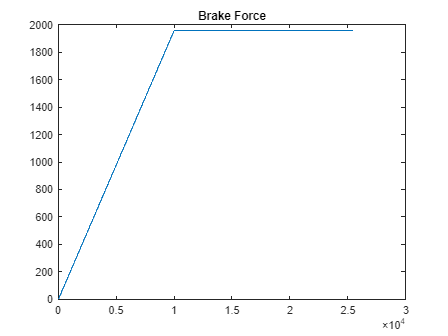

title("Brake Force")

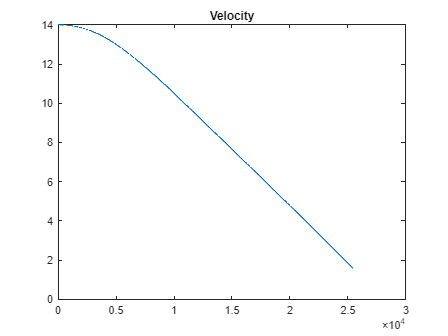

plot(logging(:,1))
title("Velocity")

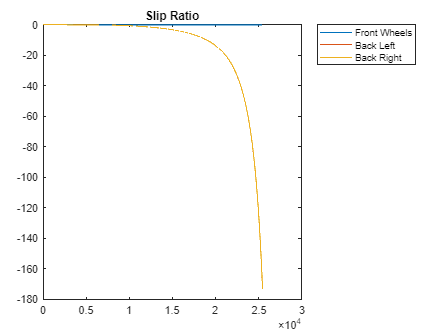

figure;
plot(logging(:,5))
hold on;
plot(logging(:,13));
plot(logging(:,17));
hold off;
title("Slip Ratio")
legend("Front Wheels", "Back Left", "Back Right", "Location","northeastoutside");

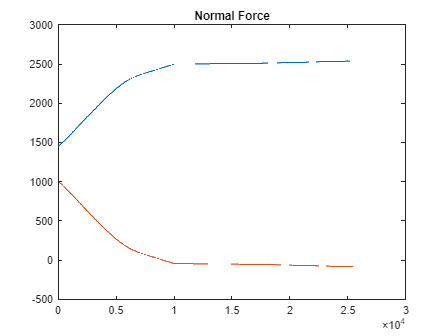

figure;
plot(logging(:,3));
hold on;
plot(logging(:,11));
hold off;
title("Normal Force")